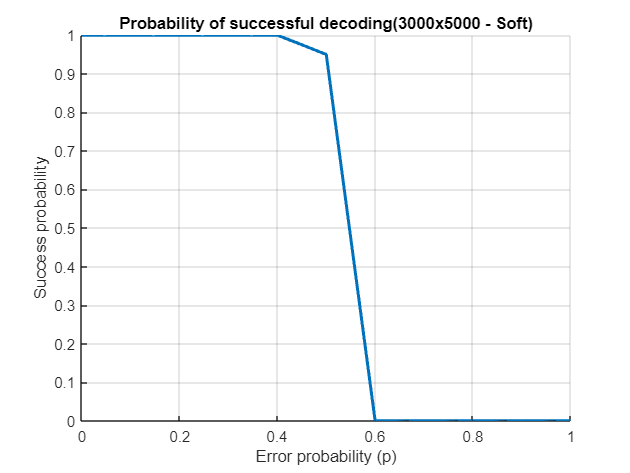

H_matrix = load("C:\Users\Admin\Desktop\DAIICT\4th sem\Commuication Systems\Lab\Lab6\Hmatrix2.mat");
H_mat = H_matrix.H;

sum_of_all_columns = sum(H_mat);
sum_of_all_rows = sum(transpose(H_mat));

dv = sum_of_all_columns(1);
dc = sum_of_all_rows(1);
u = length(sum_of_all_rows);
n = length(sum_of_all_columns);

check_nodes = zeros(u,2*dc);

for i = 1:u
    k = 1;
    for j = 1:n
        if H_mat(i,j)==1
            check_nodes(i,k) = j;
            k = k + 1;
        end
    end
end

variable_nodes = zeros(n,2*dv + 1);

for i = 1:n
    k = 2;
    for j = 1:u
        if H_mat(j,i)==1
            variable_nodes(i,k) = j;
            k = k + 1;
        end
    end
end


max_iterations = 50;
actual_codeword = zeros(1,n);
p = 0:0.1:1;
N = 100;
success_probability = zeros(size(p));
k = 1;

for perror = p
    success = 0;
    for Nsim = 1:N
        [c_received,total_no_of_errors] = bec_channel(perror,n);
        [decoded_codeword, errors_iterations] = decoding_received_msg( c_received, check_nodes, variable_nodes, u, n, dv, dc, max_iterations);
        if(sum(decoded_codeword)==0)
            success = success + 1;
        end
    end
    success_probability(k) = success/N;
    k = k + 1;
end

hold on;
plot(p,success_probability,'linewidth',2);
xlabel('Error probability (p)');
ylabel('Success probability');
title('Probability of successful decoding(3000x5000 - Soft)');
grid on;
hold off;

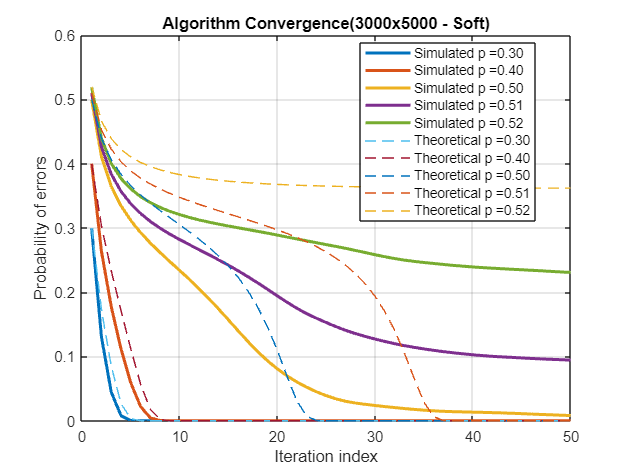


max_iterations = 50;
p = [0.3 0.4 0.5 0.51 0.52];
N = 100;

for perror = p
    error = zeros(1,max_iterations);
    for Nsim = 1:N
        [c_received,total_no_of_errors] = bec_channel(perror,n);
        [decoded_codeword, errors_iterations] = decoding_received_msg( c_received, check_nodes, variable_nodes, u, n, dv, dc, max_iterations);
        error = error + errors_iterations;
    end
    error = error./(N*n);
    plot(error,'DisplayName',sprintf('Simulated p =%.2f', perror),'linewidth',2);
    hold on;
end
legend('show','location','best');
grid on;
ylabel('Probability of errors');
xlabel('Iteration index');
title('Algorithm Convergence(3000x5000 - Soft)');

%theoretical 
p1 = [0.3, 0.4, 0.5, 0.51, 0.52];

for pError = p1
    previous = pError;
    errorProb = zeros(1, max_iterations);
    
    for i = 1:max_iterations
        errorProb(i) = previous;
        next = pError * (1 - (1-previous)^(dc-1))^(dv-1);
        previous = next;
    end
    plot(errorProb,'--','DisplayName',sprintf('Theoretical p =%.2f', pError));
end

hold off;

function [decoded_msg, error_iteration] = decoding_received_msg(cerr, cn, vn, u, n, dv, dc, m_itr)
        error_iteration = zeros(1,m_itr);
        decoded_msg = cerr;
        for i = 1:n
            vn(i,1)=decoded_msg(1,i);
        end
        for i = 1:u
            for j = (dc+1):(2*dc)
                if(vn( cn(i,j-dc), 1 ) == 0)
                    cn(i,j) = 0;
                elseif(vn( cn(i,j-dc),1 ) == 1)
                        cn(i,j) = 1;
                else
                    cn(i,j) = 0.5;
                end
            end
        end

        for i = 1:m_itr
            s = sum(vn);
            error_iteration(1,i) = abs(s(1));
            
            for j = 1:u
                for k = 1:dc
                    probability = 1;
                    for calc_p = (dc+1):2*dc
                        if( (dc+k) ~= calc_p )
                            probability = probability * (1-(2*cn(j,calc_p)));
                        end
                    end
                    for calc_p = 2:(1+dv)
                        if(vn(cn(j,k),calc_p) == j)
                            vn(cn(j,k),(calc_p+dv))=(1-probability)/2;
                            break;
                        end
                    end
                end
            end
            
            for j = 1:n
                if(decoded_msg(1,j)==0)
                    pofbeing1 = 0;
                elseif(decoded_msg(1,j)==1)
                    pofbeing1 = 1;
                else
                    pofbeing1 = 0.5;
                end
                pofbeing0 = 1 - pofbeing1;
                p0 = pofbeing0;
                p1 = pofbeing1;

                for k = (dv+2):(2*dv+1)
                    pofbeing0 = pofbeing0 * (1-vn(j,k));
                    pofbeing1 = pofbeing1 * vn(j,k);
                end

                if(pofbeing0>pofbeing1)
                    vn(j,1)=0;
                else
                    vn(j,1)=1;
                end
                
                for idx = 2:dv+1
                    for k = (dv+2):(2*dv+1)
                        if idx+dv==k
                            continue
                        else
                            p0 = p0 * (1-vn(j,k));
                            p1 = p1 * vn(j,k);
                        end
                    end
                end

                for x = 1:dc
                    for q = 2:dv+1
                        if(cn(vn(j,q),x)==j)
                            cn(vn(j,q),(x+dc)) = p1/(p1+p0);
                        end
                    end
                end
            end
        end
        decoded_msg = vn(:,1);
end

function [c_received,tot_errors] = bec_channel(k,n)
    c_received = zeros(1,n);
    tot_errors = 0;
    for i = 1:n
        if(rand()<=k)
            c_received(i) = -1;
            tot_errors = tot_errors + 1;
        end
    end
end